# Teorema fundamental del cálculo 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

 Una conexión profunda entre el cálculo diferencial e integral es la relación entre [funciones de acumulación](matlab:open('./Riemann.mlx')) y [funciones derivadas](https://www.mathworks.com/matlabcentral/fileexchange/99249-calculus-derivatives). 

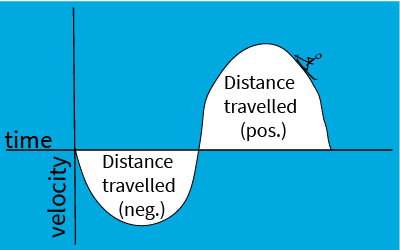

El área geométrica bajo una curva corresponde a la acumulación total del producto de los valores seguidos a lo largo de cada eje. En esta imagen, la velocidad multiplicada por el tiempo es distancia. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña **View** de la barra de herramientas de MATLAB, en la sección** View**, selecciona **Hide Code**. Alternativamente, selecciona **Hide Code **usando el ícono   en la parte superior derecha del panel del Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considera tomar el [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, sigue las instrucciones y pasos en la secuencia indicada. Pasa a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan fuera de orden. 

## Teorema fundamental del cálculo, forma derivada 

 
$$\frac{d}{dx}\left[\int_a^x f(t)\; dt \right]$$

$$=\lim_{\epsilon \to 0}\frac{\int_x^{x+\epsilon}f(t)\; dt}{\epsilon} = \lim_{\epsilon \to 0} \frac{f(x)\cdot (x+\epsilon-x)}{\epsilon} = f(x)$$


figure
clear f
syms t
f(t) =  t^2;
a = -2;
x = 3;

Para considerar un límite como $\epsilon \to 0$ , es importante considerar valores tanto positivos como negativos de `epsilon`. Para facilitar una aproximación cercana a cero, el control deslizante le permite establecer el exponente $n$ en la expresión $\epsilon = 10^n$ de modo que el control deslizante presente valores de aproximadamente 1.26 a 1e-8. 

EpsNeg = false;    EpsExp = 0;
epsilon = (-1)^EpsNeg*10^(EpsExp);
tAll = -5:.01:5;
try
    plot(tAll,f(tAll),"-",SeriesIndex="none")
catch
    plot(tAll,f(tAll),"k-")
end
ax = gca;
cmap = colororder;
hold on
if a <= x
    % Si la integración es de izquierda a derecha, colorea el área base en azul
    tVals = a:.01:x;
    % ColChoice = "#0072BD";
    ColChoice = cmap(1,:);
else
    % If the integration is right-to-left, color the base area in orange
    % and print a warning
    tVals = x:.01:a;
    % ColChoice = "#D95319";
    ColChoice = cmap(2,:);
    warning("Estás invirtiendo la dirección de la integración de izquierda a derecha a derecha a izquierda")
end
leftmax = min(a,x);
rightmin = max(a,x)+.1;

 Utilice estos controles para ampliar su región de interés: 

xleft = -5;
xright = 5;
 
% Fija el color ExtraArea para que sea dorado.
if EpsNeg
    ColeChoice = cmap(4,:); %#ok<UNRCH>
else
    ColeChoice = cmap(3,:);
end
% ColeChoice = "#EDB120";
yVals = f(tVals);
tpeVals = linspace(x,x+epsilon,50);
ypeVals = f(tpeVals);
BaseArea = area(tVals,yVals,"FaceColor",ColChoice);
ExtraArea = area(tpeVals,ypeVals,"FaceColor",ColeChoice);
xlim([xleft xright])
fxVal = double(vpa(subs(f,x)));
AreaVal = double(vpa(int(f,t,x,x+epsilon)))/epsilon;
%intfVal = int(f,t,x,x+eps);
TopyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
BottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
LeftxVal = xleft+.1*(xright-xleft);
MidxVal = (xleft+xright)/2;
BottomxVal = xleft+.4*(xright-xleft);
text(LeftxVal,TopyVal,"$f(x) = $"+fxVal,"Interpreter","latex")
text(MidxVal,TopyVal,"$\left(\int_x^{x+\epsilon} f(t)\; dt\right)/\epsilon =$ "+AreaVal,"Interpreter","latex")
text(BottomxVal,BottomyVal,"$\epsilon = $"+epsilon,"Interpreter","latex")
hold off

## Teorema fundamental del cálculo, forma antiderivada 

$\displaystyle F(x) = C+ \int_{c}^x f(t)\; dt$ es la cantidad total acumulada desde cualquier punto $c$ hasta el punto $x$ más una constante arbitraria $C$. Entonces el monto total acumulado entre $t=a$ y $t=b$ es 


$$\int_a^b f(t)\; dt = \int_{c}^b f(t)\; dt - \int_{c}^a f(t)\; dt = \left(C+ \int_{c}^b f(t)\; dt\right) - \left(C+ \int_{c}^a f(t)\; dt\right) = F(b)-F(a).$$


 Es decir, el monto acumulado entre $a$ y $b$ es el monto total que se acumuló desde el principio de los tiempos hasta el tiempo $b$ menos todo lo que se había acumulado desde el principio de tiempo hasta $a$. 

figure
syms t
f(t) = sin(t);
a = -2;         b = 1;
c = -200;          C = 0;
AreaFlag = false;            
if ~exist("tAll","var")
    tAll = -5:.01:5;
end
syms x
F(x) = int(f,t,c,x);
FAVal = double(subs(F,a)+C);
FBVal = double(subs(F,b)+C);
try
    plot(tAll,f(tAll),"-",SeriesIndex="none")
catch
    plot(tAll,f(tAll),"k-")
end

ax = gca;
hold on
if a <= b
    % Si el área se acumula a la derecha de a, colorea el área en azul
    tVals = a:.01:b;
    ColChoice = cmap(1,:);
%    ColChoice = "#00a9e0";
else
    % Si la integración se elimina a la izquierda de a, colorea el área de naranja
    tVals = b:.01:a;
    ColChoice = cmap(2,:);
%    ColChoice = "#004b87";
end
% Arreglar el color extraArea para que sea morado.
ColeChoice = cmap(4,:);
% ColeChoice = "#7730ba";
yVals = f(tVals);
tpeVals = -5:.01:min(a,b);
ypeVals = f(tpeVals);
OverlapArea = area(tVals,yVals,"FaceColor",ColChoice);
if ~AreaFlag
    ExtraArea = area(tpeVals,ypeVals,"FaceColor",ColeChoice);
end
TopyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
BottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
LeftxVal = ax.XLim(1)+.1*(ax.XLim(2)-ax.XLim(1));
MidxVal = (ax.XLim(1)+ax.XLim(2))/2;
BottomxVal = ax.XLim(1)+.4*(ax.XLim(2)-ax.XLim(1));
text(LeftxVal,TopyVal,"$F(b) = $"+FBVal,"Interpreter","latex")
text(MidxVal,TopyVal,"$F(a) = $ "+FAVal,"Interpreter","latex")
text(BottomxVal,BottomyVal,"$F(b)-F(a) = $"+double(int(f,a,b)),"Interpreter","latex")
plot([a a],[min(yVals) max(yVals)],"r-")
plot([b b],[min(yVals) max(yVals)],"r-")
xNL = ["a = "+a "b = "+b "-5" "0" "5"];
[xNameVals,idxA,~] = unique([a b -5 0 5]);
xNameLabels = xNL(idxA);
xticks(xNameVals);
xticklabels(xNameLabels);
hold off

[⇦ Menú principal](matlab:open('MainMenu.mlx'))